# 4AX3: A2 - suitorj - 400138679

## Continous Representation

Continous state space representation of the system.


$$\left\lbrack \begin{array}{c}
\textrm{ax}\\
\textrm{vx}\\
\textrm{ay}\\
\textrm{vy}
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 0 & 0 & 0\\
1 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\textrm{vx}\\
\textrm{px}\\
\textrm{vy}\\
\textrm{py}
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
-g\\
0
\end{array}\right\rbrack$$


## Discrete Representation

Discrete state space representation of the system with some step size h.


$$\left\lbrack \begin{array}{c}
\textrm{vx}\left(n+1\right)\\
\textrm{px}\left(n+1\right)\\
\textrm{vy}\left(n+1\right)\\
\textrm{py}\left(n+1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
h & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & h & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\textrm{vx}\left(n\right)\\
\textrm{px}\left(n\right)\\
\textrm{vy}\left(n\right)\\
\textrm{py}\left(n\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
-h*g\\
0
\end{array}\right\rbrack$$


## Setup

x0 = 0; % x initial position
y0 = 0; % y initial position
v = 10; % initial velocity
alpha = 45; % launch angle
global g;
g = 9.81; % Gravity value
vx = cosd(alpha) * v; % Initial x velocity
vy = sind(alpha) * v; % Initial y velocity

## System Solution

System representation using the system solutions provided.

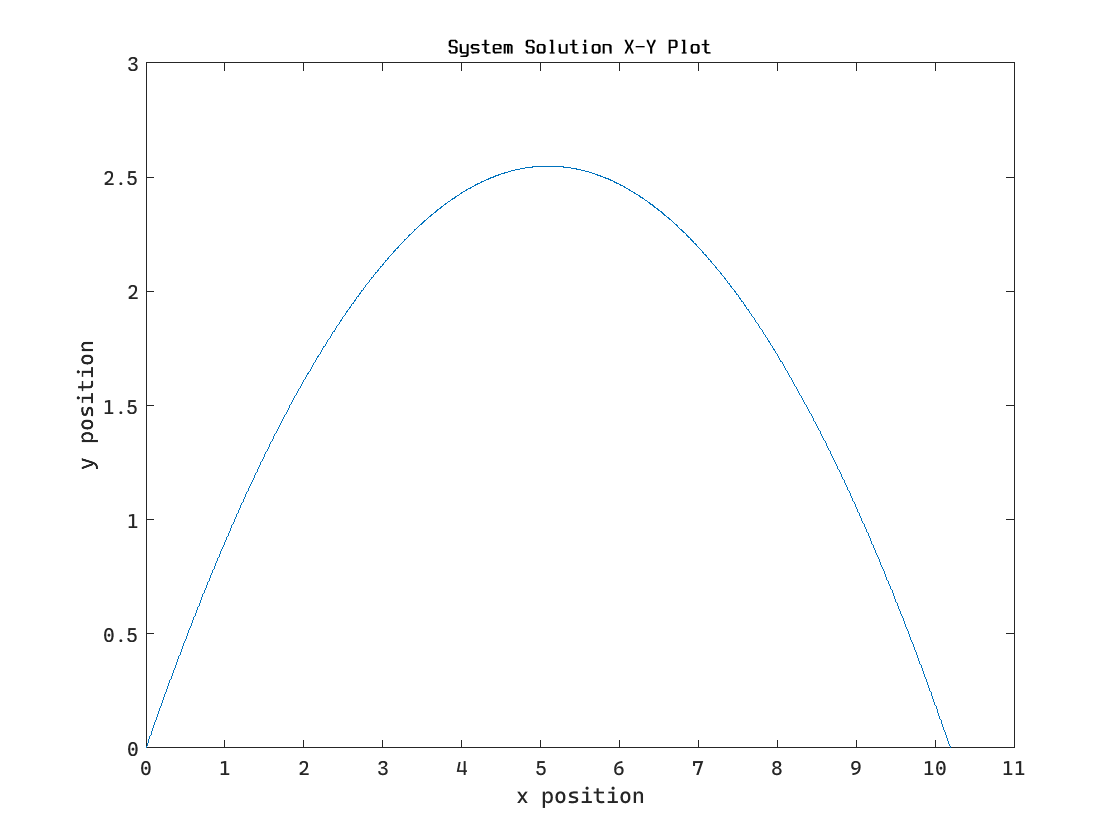

t = 0:0.001:1.5;
x = x0 + vx*t;
y = y0 + vy*t - g/2*t.^2;
plot_solution(x, y, "System Solution X-Y Plot")

## Continous System

Continous system simulation. Due to Matlab limitations the continous system function can be found at the end of this document.

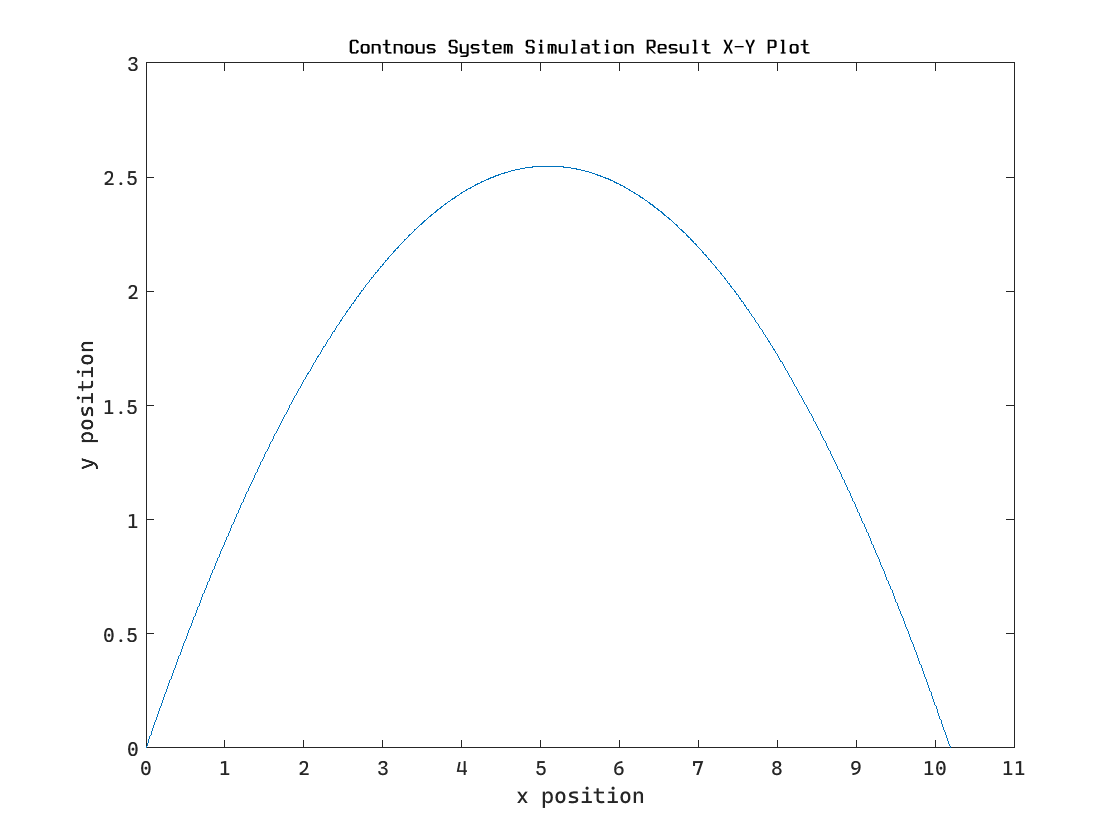

initial = [x0, vx, y0, vy];
[t,out] = ode45(@ode_func, t, initial);
plot_solution(out(:,1), out(:,3), "Contnous System Simulation Result X-Y Plot")

## Discrete System

Discrete system simulation

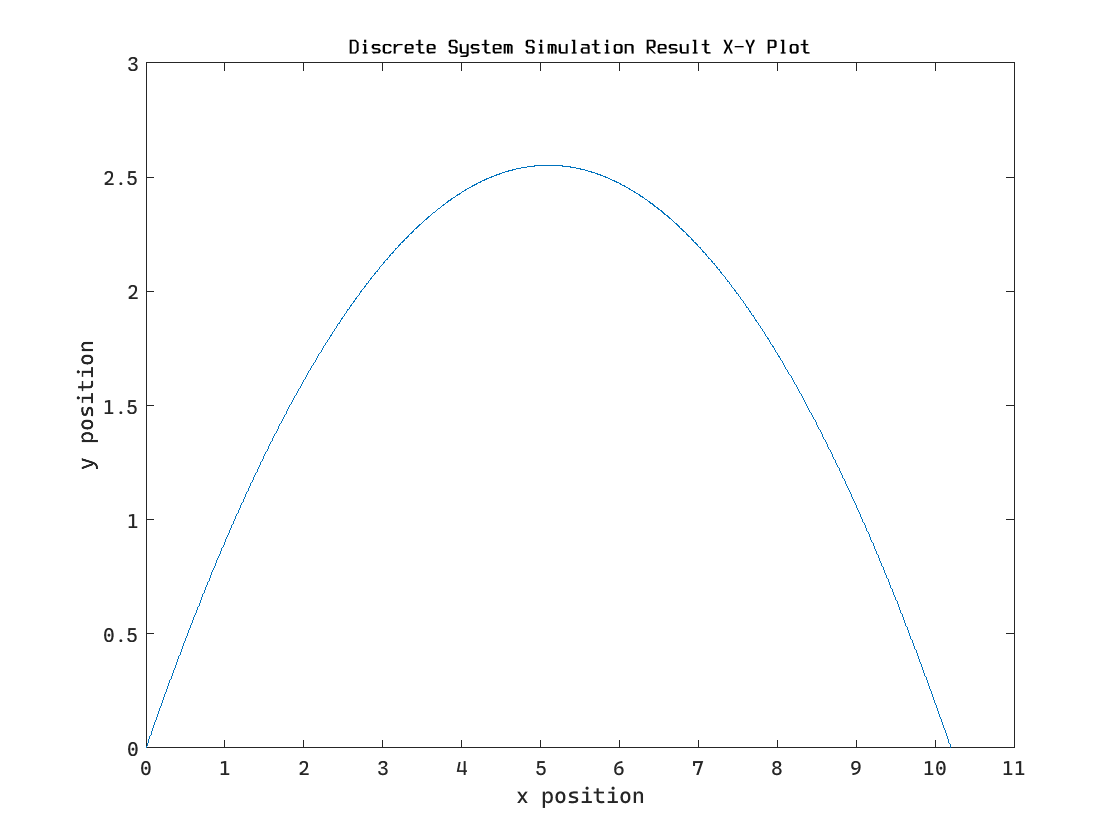

vx_d = []; vx_d(1) = vx; % Set x velocity initial value
vy_d = []; vy_d(1) = vy; % Set y velocity initial value
px_d = []; px_d(1) = x0; % Set x position initial value
py_d = []; py_d(1) = y0; % Set y position initial value
h = 0.001; % Set the step size of the discrete system
i = 1;
while py_d(i) >= 0 % Until the projectile contacts the ground
    vx_d(i+1) = vx_d(i); % vx
    vy_d(i+1) = vy_d(i) - g*h; % vy
    px_d(i+1) = px_d(i) + vx_d(i)*h; %px
    py_d(i+1) = py_d(i) + vy_d(i)*h; % py
    i = i + 1; % Increment
end
plot_solution(px_d, py_d, "Discrete System Simulation Result X-Y Plot")

## Functions

function out = ode_func(~,Y)
    global g;
    out = zeros(4,1);
    out(1) = Y(2); %vx
    out(2) = 0;    %ax
    out(3) = Y(4); %vy
    out(4) = -g;   %ay
end


function plot_solution(x, y, title_string)
    plot(x,y)
    ylim([0,3])
    xlim([0, 11])
    title(title_string)
    xlabel("x position")
    ylabel("y position")
end